clear; close('all'); clc;
start_toolkit;

EPANET-MATLAB Toolkit Paths Loaded.


d = epanet('group 3 .inp');

EPANET version {20305} loaded (EMT version {v2.3.5.2 - Last Update: 03/03/2026}).
<a href = "https://doi.org/10.5281/zenodo.831493">Publication DOI: 10.5281/zenodo.831493</a>
Loading File "group 3 .inp"...
Input File "group 3 .inp" loaded successfully.


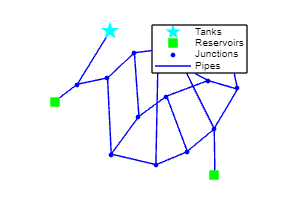

d.plot;

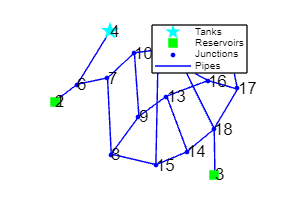

ans =   Axes with properties:

             XLim: [-5.8272e+03 1.1936e+04]
             YLim: [2.7973e+03 9.8830e+03]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


d.plot('nodes', 'yes', 'fontsize', 14)

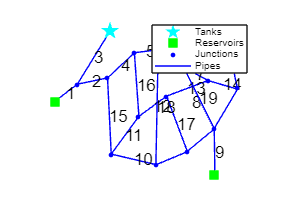

ans =   Axes with properties:

             XLim: [-5.8272e+03 1.1936e+04]
             YLim: [2.7973e+03 9.8830e+03]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


d.plot('links', 'yes', 'fontsize', 14)

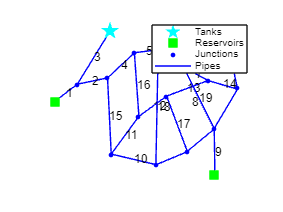

d.plot('linksindex', 'yes', 'fontsize',10);

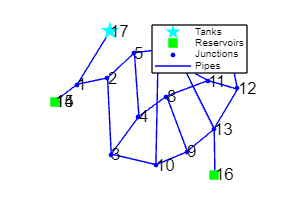

d.plot('nodesindex', 'yes', 'fontsize',14);

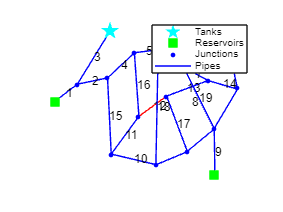

d.plot('links', 'yes', 'highlightlink',{'12'}, 'fontsize',10);  

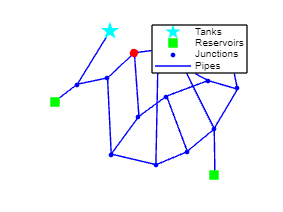

d.plot('highlightnode',{'10', '32'});

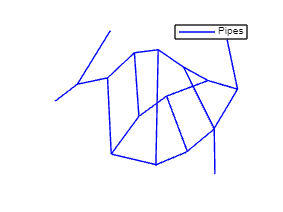

d.plot('point', 'no');

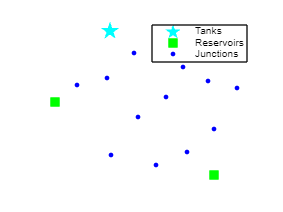

d.plot('line', 'no');

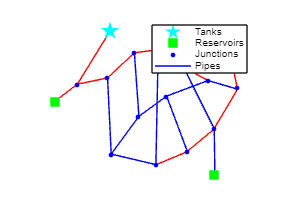

ans =   Axes with properties:

             XLim: [-5.8272e+03 1.1936e+04]
             YLim: [2.7973e+03 9.8830e+03]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


linkSet1 = d.getLinkNameID(1:4);
colorLinkSet1 = repmat({'r'},1,length(linkSet1));
linkSet2 = d.getLinkNameID([5,6,7,8]);
colorLinkSet2=repmat({'r'},1,length(linkSet2));
d.plot('highlightlink',[linkSet1 linkSet2],'colorlink',[colorLinkSet1 colorLinkSet2])

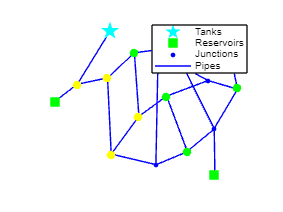

ans =   Axes with properties:

             XLim: [-5.8272e+03 1.1936e+04]
             YLim: [2.7973e+03 9.8830e+03]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


nodeSet1 = d.getNodeNameID(1:4);
colorLinkSet1 = repmat({'y'},1,length(nodeSet1));
nodeSet2 = d.getNodeNameID([5,6,7,8,9,12]);
colorLinkSet2=repmat({'g'},1,length(nodeSet2));
d.plot('highlightnode',[nodeSet1 nodeSet2],'colornode',[colorLinkSet1 colorLinkSet2])

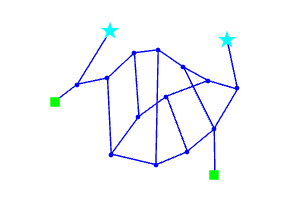

ans =   Axes with properties:

             XLim: [-5.8272e+03 1.1936e+04]
             YLim: [2.7973e+03 9.8830e+03]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


d.plot('legend', 'hide')

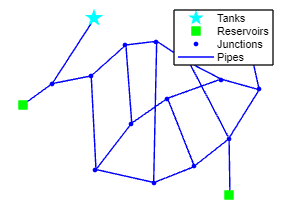

ans =   Axes with properties:

             XLim: [-5.8272e+03 1.1936e+04]
             YLim: [2.7973e+03 9.8830e+03]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0 0 1 1]
            Units: 'normalized'

  Show all properties


EPANET version {20305} loaded (EMT version {v2.3.5.2 - Last Update: 03/03/2026}).
<a href = "https://doi.org/10.5281/zenodo.831493">Publication DOI: 10.5281/zenodo.831493</a>
Loading File "group 3 .inp"...
Input File "group 3 .inp" loaded successfully.


hyd_res_1 = struct with fields:
              Time: [101×1 double]
          Pressure: [101×18 single]
            Demand: [101×18 single]
              Head: [101×18 single]
       NodeQuality: [101×18 single]
              Flow: [101×19 single]
          Velocity: [101×19 single]
          HeadLoss: [101×19 single]
            Status: [101×19 single]
           Setting: [101×19 single]
      ReactionRate: [101×19 single]
    FrictionFactor: [101×19 single]
       LinkQuality: [101×19 single]
      EnergyReport: [1×1 struct]
         StatusStr: {101×19 cell}


hyd_res_2 = struct with fields:
              Time: [101×1 double]
          Pressure: [101×18 single]
            Demand: [101×18 single]
              Head: [101×18 single]
       NodeQuality: [101×18 single]
              Flow: [101×19 single]
          Velocity: [101×19 single]
          HeadLoss: [101×19 single]
            Status: [101×19 single]
           Setting: [101×19 single]
      ReactionRate: [101×19 single]
    FrictionFactor: [101×19 single]
       LinkQuality: [101×19 single]
      EnergyReport: [1×1 struct]
         StatusStr: {101×19 cell}


Elapsed time for the function `getComputedTimeSeries` is: 1.4668


Elapsed time for the function `getComputedTimeSeries_ENepanet` is: 0.22139


Elapsed time for the function `getComputedHydraulicTimeSeries` is: 0.25686


Elapsed time for the function `step-by-step` is: 0.22085


d.plot('extend', 'yes')